P = struct();
P.a1 = -100;    P.a5 = -100;
P.b1 = 100;     P.b5 = -100;
P.c1 = 50;      P.c5 = P.c1;

P.r2 = 100;     P.r6 = 100;

P.r3 = 100;     P.r7 = 100;

P.a4 = 100;     P.a8 = 0;
P.b4 = 0;       P.b8 = 100;
P.c4 = 50;      P.c8 = P.c4;

P.theta = [0; 0];

% [theta1, theta2] = meshgrid(0,(-pi/12:pi/36:pi/12)');
% [theta1, theta2] = meshgrid((-pi/12:pi/36:pi/12)',0);
% [theta1, theta2] = meshgrid(0,0);
% theta = 0;

theta1 = pi/12*cos(0:pi/24:4*pi);
theta2 = pi/12*sin(0:pi/24:4*pi);

phi=zeros(numel(theta1),2);

for n=1:numel(theta1)
    P.theta = [theta1(n); theta2(n)];
    fcn = @(phi) minfun(phi, P);
    phi(n,:) = fminsearch(fcn,[0;0]);
end

theta = [theta1(:) theta2(:)];

% hf1 = figure(1);
% plot(theta1,phi)
% grid on;

## Post Processing

N = length(theta);

[sf.x, sf.y, sf.z] = meshgrid(-P.a4:P.a4:P.a4, -P.b8:P.b8:P.b8, P.c4);
[sf2.x, sf2.y, sf2.z] = meshgrid(-P.a1:P.a1:P.a1, -P.b5:P.b5:P.b5, -P.c1);

sf.Ax = zeros([size(sf.x) N]);
sf.Ay = zeros([size(sf.y) N]);
sf.Az = zeros([size(sf.z) N]);

for n=1:N
    Rx = [  1               0               0
            0               cos(phi(n,1))  -sin(phi(n,1))
            0               sin(phi(n,1))   cos(phi(n,1))];
        
    Ry = [  cos(phi(n,2))   0               sin(phi(n,2))
            0               1               0
           -sin(phi(n,2))   0               cos(phi(n,2))];
        
    Rxy = Rx*Ry;
    
    pts.x1(n) = P.a1;
    pts.y1(n) = P.b1;
    pts.z1(n) = P.c1;
    
    pts.x2(n) = 0;
    pts.y2(n) = P.r2*cos(theta(n,1));
    pts.z2(n) = P.r2*sin(theta(n,1));
    
    xyz4 = Rxy*[P.a4; P.b4; P.c4];
    pts.x4(n) = xyz4(1);
    pts.y4(n) = xyz4(2);
    pts.z4(n) = xyz4(3);
    
    pts.x3(n) = pts.x1(n) - pts.x2(n) + pts.x4(n);
    pts.y3(n) = pts.y1(n) - pts.y2(n) + pts.y4(n);
    pts.z3(n) = pts.z1(n) - pts.z2(n) + pts.z4(n);
    
    pts.xx(n,:) = [-pts.x1(n)  -pts.x1(n)+pts.x2(n)  -pts.x1(n)+pts.x2(n)+pts.x3(n)  -pts.x1(n)+pts.x2(n)+pts.x3(n)-pts.x4(n)];
    pts.xy(n,:) = [-pts.y1(n)  -pts.y1(n)+pts.y2(n)  -pts.y1(n)+pts.y2(n)+pts.y3(n)  -pts.y1(n)+pts.y2(n)+pts.y3(n)-pts.y4(n)];
    pts.xz(n,:) = [-pts.z1(n)  -pts.z1(n)+pts.z2(n)  -pts.z1(n)+pts.z2(n)+pts.z3(n)  -pts.z1(n)+pts.z2(n)+pts.z3(n)-pts.z4(n)];
    
    pts.x5(n) = P.a5;
    pts.y5(n) = P.b5;
    pts.z5(n) = P.c5;
    
    pts.x6(n) =-P.r6*cos(theta(n,2));
    pts.y6(n) = 0;
    pts.z6(n) = P.r6*sin(theta(n,2));
    
    xyz8 = Rxy*[P.a8; P.b8; P.c8];
    pts.x8(n) = xyz8(1);
    pts.y8(n) = xyz8(2);
    pts.z8(n) = xyz8(3);
    
    pts.x7(n) = pts.x5(n) - pts.x6(n) + pts.x8(n);
    pts.y7(n) = pts.y5(n) - pts.y6(n) + pts.y8(n);
    pts.z7(n) = pts.z5(n) - pts.z6(n) + pts.z8(n);
    
    pts.yx(n,:) = [-pts.x5(n)  -pts.x5(n)+pts.x6(n)  -pts.x5(n)+pts.x6(n)+pts.x7(n)  -pts.x5(n)+pts.x6(n)+pts.x7(n)-pts.x8(n)];
    pts.yy(n,:) = [-pts.y5(n)  -pts.y5(n)+pts.y6(n)  -pts.y5(n)+pts.y6(n)+pts.y7(n)  -pts.y5(n)+pts.y6(n)+pts.y7(n)-pts.y8(n)];
    pts.yz(n,:) = [-pts.z5(n)  -pts.z5(n)+pts.z6(n)  -pts.z5(n)+pts.z6(n)+pts.z7(n)  -pts.z5(n)+pts.z6(n)+pts.z7(n)-pts.z8(n)];
    

    sf.A = [sf.x(:) sf.y(:) sf.z(:)]*Rxy';
    sf.Ax(:,:,n) = reshape(sf.A(:,1),[3 3]);
    sf.Ay(:,:,n) = reshape(sf.A(:,2),[3 3]);
    sf.Az(:,:,n) = reshape(sf.A(:,3),[3 3]);
    
    
    orig.x(n,:) = [0 50*Rxy(1,3)];
    orig.y(n,:) = [0 50*Rxy(2,3)];
    orig.z(n,:) = [0 50*Rxy(3,3)];
end

## Animation

hf2 = figure(2);
hf2.Visible = 'on';
frames = cell(N,1);
for n = 1:length(theta)
    figure(hf2);
    
    % Motor Arm 1
    plot3(pts.xx(n,1:2), pts.xy(n,1:2), pts.xz(n,1:2),'-oblack','linewidth',4);
    hold on
    
    % Push Rod 1
    plot3(pts.xx(n,2:3), pts.xy(n,2:3), pts.xz(n,2:3),'-oblack','linewidth',3);
    
    % Platform mount 1
    plot3(pts.xx(n,3:4), pts.xy(n,3:4), pts.xz(n,3:4),'--black','linewidth',2);
    
    % Origin
    plot3(orig.x(n,:), orig.y(n,:), orig.z(n,:),'--oblack','linewidth',2);
    
    % Path for pushrod 1
    plot3(pts.xx(1:n,2), pts.xy(1:n,2), pts.xz(1:n,2), ':black', 'linewidth',1);
    plot3(pts.xx(1:n,3), pts.xy(1:n,3), pts.xz(1:n,3), ':black', 'linewidth',1);
    
    % Motor Arm 2
    plot3(pts.yx(n,1:2), pts.yy(n,1:2), pts.yz(n,1:2), '-oblack','linewidth',4);
    
    % Push Rod 2
    plot3(pts.yx(n,2:3), pts.yy(n,2:3), pts.yz(n,2:3), '-oblack','linewidth',3);
    
    % Platform mount 2
    plot3(pts.yx(n,3:4), pts.yy(n,3:4), pts.yz(n,3:4), '--black','linewidth',2);
    
    % Path for pushrod 2
    plot3(pts.yx(1:n,2), pts.yy(1:n,2), pts.yz(1:n,2), ':black', 'linewidth',1);
    plot3(pts.yx(1:n,3), pts.yy(1:n,3), pts.yz(1:n,3), ':black', 'linewidth',1);
    
    % Platform
    hs1 = surf(sf.Ax(:,:,n), sf.Ay(:,:,n), sf.Az(:,:,n),'FaceColor',"blue");
    alpha(hs1,0.4);
    
    % Base
    hs2 = surf(sf2.x, sf2.y, sf2.z,'FaceColor',"cyan");
    alpha(hs2,1);
    
    hold off
    axis equal
    axis([-200 200 -200 200 -100 200]);
    grid on;
    box on;
%     view([60 15]);
    view([60 30]);
%     view([30 30 ]);
%     view([-45 30 ]);
%     view([0 0]);
%     view([90 0]);
%     view([168 15]);
%     view([180 0]);
%     pause(0.1);
    drawnow('limitrate');
    frames{n} = frame2im(getframe(hf2));
end

% filename = "balancing_platform_rolling.gif";
% fps = 30;
% 
% for n=1:N
%     [A,map] = rgb2ind(frames{n},256);
%     if n == 1
%         imwrite(A,map,filename,'gif','LoopCount',Inf,'DelayTime',1/fps);
%     elseif n==length(frames)
%         imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',2);
%     else
%         imwrite(A,map,filename,'gif','WriteMode','append','DelayTime',1/fps);
%     end
% end
% fprintf('File %s generated succesffully.', filename);

## Linearizing

We want to best-fit our data to the linear form $\left[ \begin{array}{cc} \phi_1 \\ \phi_2 \end{array} \right] = 
\left[ \begin{array}{cc} M_{11} & M_{12} \\ M_{21} & M_{22} \end{array} \right] 
\left[ \begin{array}{cc} \theta_1 \\ \theta_2 \end{array} \right] +
\left[ \begin{array}{cc} b_1 \\ b_2 \end{array} \right]$. We begin by adjusting the equation to appear as$\left[ \begin{array}{cc} \phi_1 \\ \phi_2 \end{array} \right] = 
\left[ \begin{array}{cc} M_{11} & M_{12} & b_1\\ M_{21} & M_{22} & b_2 \end{array} \right] 
\left[ \begin{array}{cc} \theta_1 \\ \theta_2 \\ 1\end{array} \right] $. Then we can recognize that if this expression is true everywhere for the best fit line, it must be approximately true for arbitrary datapoint $n$; therefore $\left[ \begin{array}{cc} \phi_1 \\ \phi_2 \end{array} \right]_n \approx 
\left[ \begin{array}{cc} M_{11} & M_{12} & b_1\\ M_{21} & M_{22} & b_2 \end{array} \right] 
\left[ \begin{array}{cc} \theta_1 \\ \theta_2 \\ 1\end{array} \right] _n$. Thus, extrapolating for every data point $n = 1 \dots N$, $\left[ \begin{array}{cc} (\phi_1)_1 & (\phi_1)_2 & \dots & (\phi_1)_N \\ (\phi_2)_1 & (\phi_2)_2 & \dots &  (\phi_2)_N \end{array} \right] \approx 
\left[ \begin{array}{cc} M_{11} & M_{12} & b_1\\ M_{21} & M_{22} & b_2 \end{array} \right] 
\left[ \begin{array}{cc} (\theta_1)_1 &  (\theta_1)_2 & \cdots &  (\theta_1)_N \\ (\theta_2)_1 &  (\theta_2)_2 & \cdots &  (\theta_2)_N \\ 1 & 1 & \cdots & 1\end{array} \right]$. For concision, this form will be represented symbolically as $Y^\top \approx \beta^\top X^\top$, or equivalently in the standard form for least-squares, $Y = X \beta$ which has the solution $\beta = \left( X^\top X \right)^{-1} X^\top Y$.

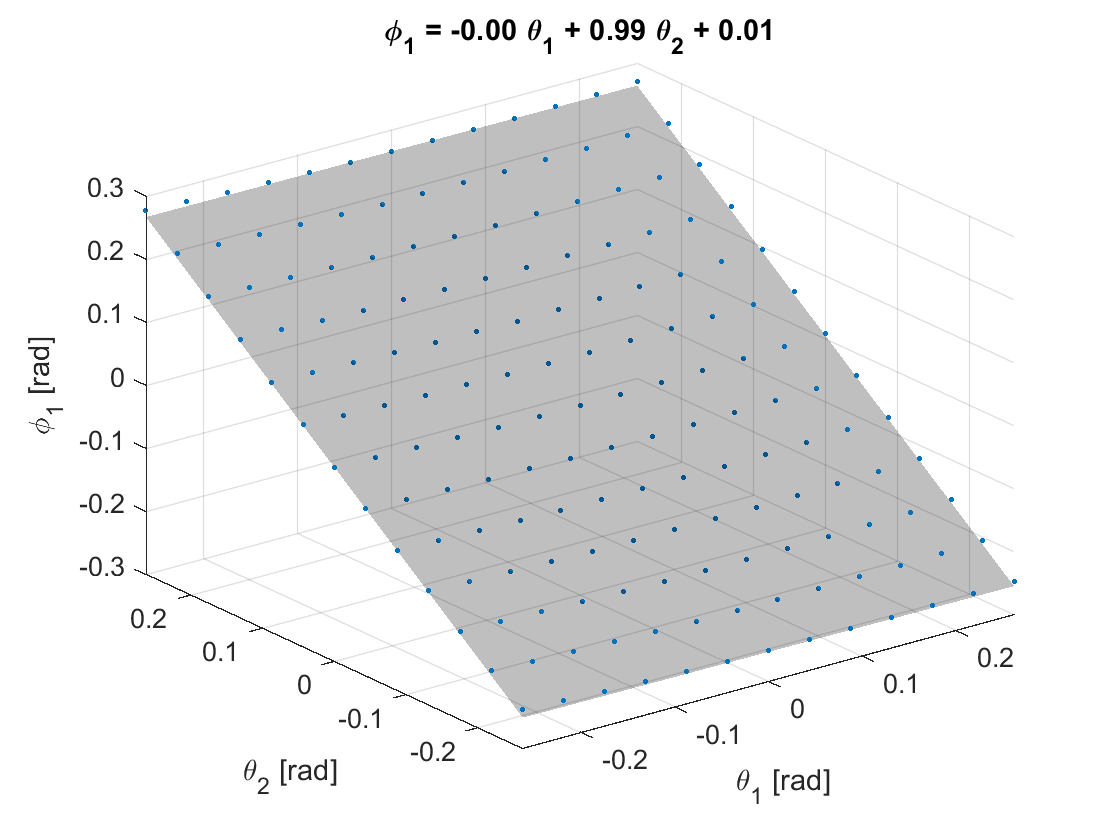

[theta1, theta2] = meshgrid((-pi/12:pi/72:pi/12)',(-pi/12:pi/72:pi/12)');

phi=zeros(numel(theta1),2);

for n=1:numel(theta1)
    P.theta = [theta1(n); theta2(n)];
    fcn = @(phi) minfun(phi, P);
    phi(n,:) = fminsearch(fcn,[0;0]);
end

theta = [theta1(:) theta2(:)];

Y = phi;
X = [theta(:,1)     theta(:,2)     ones(length(theta),1)];
% beta = inv(X'*X)*(X'*Y);
beta  = X\Y;

M = beta(1:2,1:2)';
b = beta(3,1:2)';

hf3 = figure(3);
    plot3(theta(:,1), theta(:,2), phi(:,1),'.');
    hold on;
%     plot3(theta(:,1), theta(:,2), M(1,1)*theta(:,1) + M(1,2)*theta(:,2) + b(1));
    xx = reshape(theta(:,1),size(theta1));
    yy = reshape(theta(:,2),size(theta2));
    zz = M(1,1)*xx+M(1,2)*yy+b(1);
    surf(xx,yy,zz,'FaceColor','black',"LineStyle","none");
    alpha 0.25
    hold off;
    grid on;
    title(sprintf('\\phi_1 = %2.2f \\theta_1 + %2.2f \\theta_2 + %2.2f',M(1,1),M(1,2),b(1)));
    xlabel('\theta_1 [rad]');
    ylabel('\theta_2 [rad]');
    zlabel('\phi_1 [rad]');

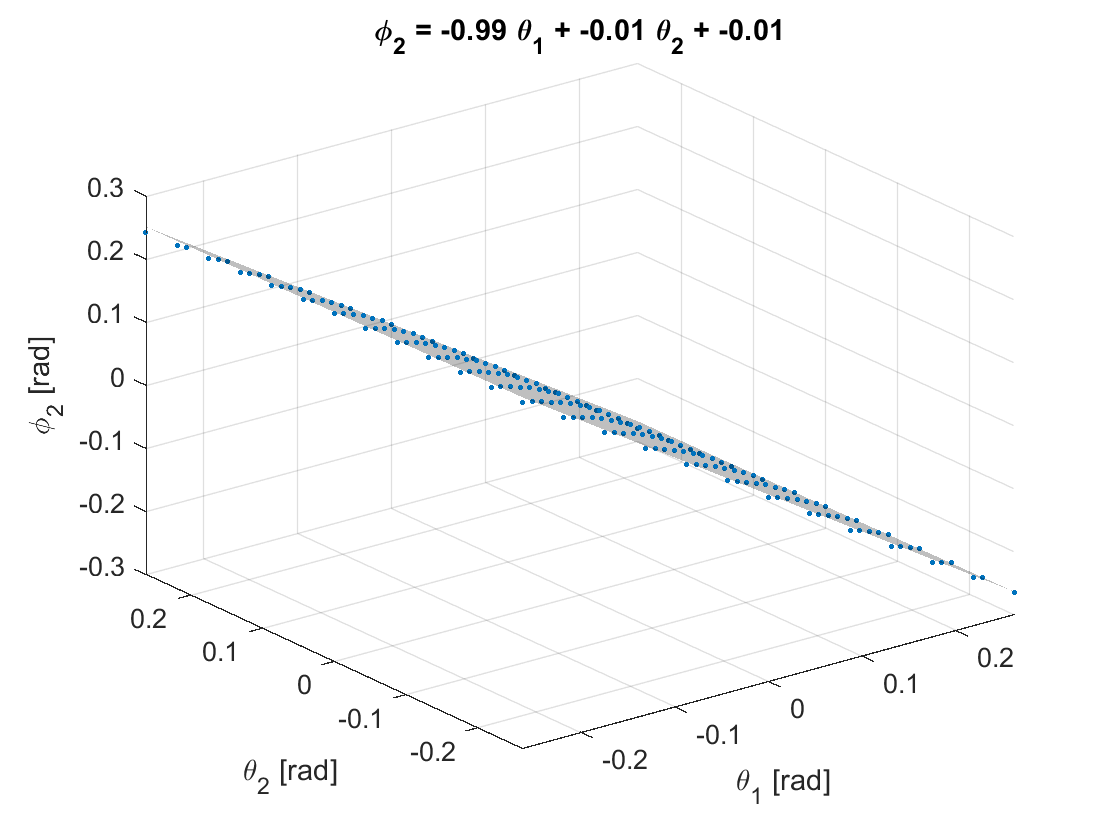

hf4 = figure(4);
    plot3(theta(:,1), theta(:,2), phi(:,2),'.');
    hold on;
%     plot3(theta(:,1), theta(:,2), M(2,1)*theta(:,1) + M(2,2)*theta(:,2) + b(2));
    xx = reshape(theta(:,1),size(theta1));
    yy = reshape(theta(:,2),size(theta2));
    zz = M(2,1)*xx+M(2,2)*yy+b(2);
    surf(xx,yy,zz,'FaceColor','black',"LineStyle","none");
    alpha 0.25
    hold off;
    grid on;
    title(sprintf('\\phi_2 = %2.2f \\theta_1 + %2.2f \\theta_2 + %2.2f',M(2,1),M(2,2),b(2)));
    xlabel('\theta_1 [rad]');
    ylabel('\theta_2 [rad]');
    zlabel('\phi_2 [rad]')

### Inverse Relationship

Its also useful to be able to predict the required motor angles needed to produce the desired platform angle.


$$\begin{array}{rl}
\mathbf{\phi} &= M \mathbf{\theta} + \mathbf{b} \\
M^{-1} \mathbf{\phi} &= \mathbf{\theta} + M^{-1} \mathbf{b} \\
\mathbf{\theta} &= M^{-1} \mathbf{\phi} - M^{-1} \mathbf{b} \\
\mathbf{\theta} &= M\prime \mathbf{\phi} + \mathbf{b}\prime
\end{array}$$


M_prime = inv(M);
b_prime = -M\b;

fprintf("The backward matrix M' = ");

The backward matrix M' = 

disp(M_prime);

   -0.0086   -1.0099
    1.0097   -0.0047



fprintf("The backward intercept b' = ");

The backward intercept b' = 

disp(b_prime);

   -0.0059
   -0.0062

